# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 5: exercise 03 - Kmeans

**Students: Filip Ćelepirović, Helena Potočki**

## Questions

Note: Fisher's iris data set consists of measurements on the (1) sepal length, (2) sepal  width, (3) petal length, and (4) petal width for 150 iris specimens (Iris is a set of species of flowering plants with showy flowers). There are 50 specimens from each of three species {setosa, versicolor and virginica}.

- Calculate the confusion matrix of the K-means algorithm using `confusionmat` function.

- Calculate the accuracy (`acc=hits/total`) of the K-means algorithm.

- (Optional) Repeat the previous sections but using petals instead of sepals (`data_iris = meas(:,``3:4``);`). In which cases are better results obtained? .

Step 1) Load data set.

clear all;
close all;

load fisheriris
data_iris = meas(:,1:2);
label_iris = categorical(species);
names_iris = categories(label_iris);

Step 2) Visualize the data set.

plot(data_iris(:,1),data_iris(:,2),'k*','MarkerSize',5);

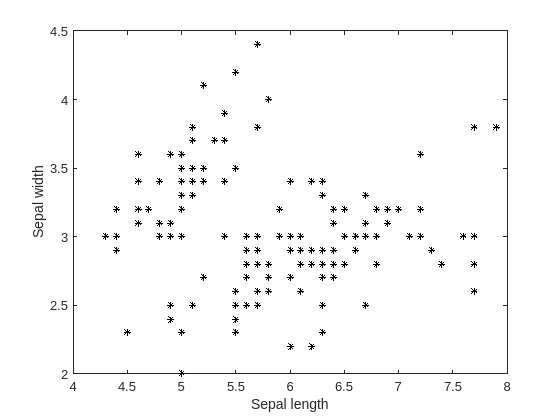

xlabel('Sepal length');
ylabel('Sepal width');

Step 3) Kmeans

[idx,C] = kmeans(data_iris,3);

'kmeans' requires Statistics and Machine Learning Toolbox.

Step 4) Plot clustering.

figure;
subplot(1,2,1)
gscatter(data_iris(:,1),data_iris(:,2), label_iris,'rgb','ooo',8,'on')
xlabel('Sepal length');
ylabel('Sepal width');
grid on;
legend('setosa','versicolor', 'virginica' ,'Location','NW')
title ('Fisher''s Iris dataset')

subplot(1,2,2)
hold on
plot(data_iris(idx==1,1),data_iris(idx==1,2),'r.','MarkerSize',12)
plot(data_iris(idx==2,1),data_iris(idx==2,2),'g.','MarkerSize',12)
plot(data_iris(idx==3,1),data_iris(idx==3,2),'b.','MarkerSize',12)
plot(C(1,1),C(1,2),'rx','MarkerSize',15,'LineWidth',3) 
plot(C(2,1),C(2,2),'gx','MarkerSize',15,'LineWidth',3) 
plot(C(3,1),C(3,2),'bx','MarkerSize',15,'LineWidth',3) 
xlabel('Sepal length');
ylabel('Sepal width');
grid on;
legend('Cluster 1','Cluster 2','Cluster 3','Centroid 1','Centroid 2','Centroid 3','Location','NW')
title ('Cluster Assignments and Centroids')
hold off

Step 5) **Results.**

% Confusion Matrix
confMat = confusionmat(label_iris, names_iris(idx));

% Accuracy
hits = sum(diag(confMat));
total = sum(confMat(:));
accuracy = hits / total;

disp('Confusion Matrix:');
disp(confMat);

disp(['Accuracy: ', num2str(accuracy * 100), '%']);
